sym funkcije

syms q1 q2 q3 a1 a2 d3
px=a1*cos(q1)+a2*cos(q1+q2)

$$px = a_{2}\,\cos\left(q_{1}+q_{2}\right)+a_{1}\,\cos\left(q_{1}\right)$$

py=a1*sin(q1)+a2*sin(q1+q2)

$$py = a_{2}\,\sin\left(q_{1}+q_{2}\right)+a_{1}\,\sin\left(q_{1}\right)$$

pz=d3

$$pz = d_{3}$$

theta=q1+q2+q3

$$theta = q_{1}+q_{2}+q_{3}$$

J=jacobian([px, py, pz, theta], [q1, q2, q3])

$$J = \left(\begin{array}{ccc} -a_{2}\,\sin\left(q_{1}+q_{2}\right)-a_{1}\,\sin\left(q_{1}\right) & -a_{2}\,\sin\left(q_{1}+q_{2}\right) & 0\\ a_{2}\,\cos\left(q_{1}+q_{2}\right)+a_{1}\,\cos\left(q_{1}\right) & a_{2}\,\cos\left(q_{1}+q_{2}\right) & 0\\ 0 & 0 & 0\\ 1 & 1 & 1 \end{array}\right)$$

stvarne vrijednosti

q1=55*pi/180;
q2=-28*pi/180;
q3=14*pi/180;
a1=72;
a2=56;
d3=-5;
Tr=8;
om1=q1/Tr

om1 = 0.1200

om2=q2/Tr

om2 = -0.0611

om3=q3/Tr

om3 = 0.0305

OM=[om1;
    om2;
    om3;]

OM =     0.1200
   -0.0611
    0.0305


funkcije

px=a1*cos(q1)+a2*cos(q1+q2)

px = 91.1939

py=a1*sin(q1)+a2*sin(q1+q2)

py = 84.4024

pz=d3

pz = -5

theta=q1+q2+q3

theta = 0.7156

jacobian

J=double(subs(J))

J =   -84.4024  -25.4235         0
   91.1939   49.8964         0
         0         0         0
    1.0000    1.0000    1.0000


vektor brzine

V=J*OM

V =    -8.5745
    7.8945
         0
    0.0894


vx=V(1,1)

vx = -8.5745

vy=V(2,1)

vy = 7.8945

vz=V(3,1)

vz = 0

kutna brzina

om=V(4,1) %om=om1+om2+om3 

om = 0.0894

linijska brzina

v=sqrt(vx^2+vy^2+vz^2)

v = 11.6553

kut brzine

kutbrzine=atan(vy*vx)*180/pi

kutbrzine = -89.1536

crtanje položaja u X-Y ravnini

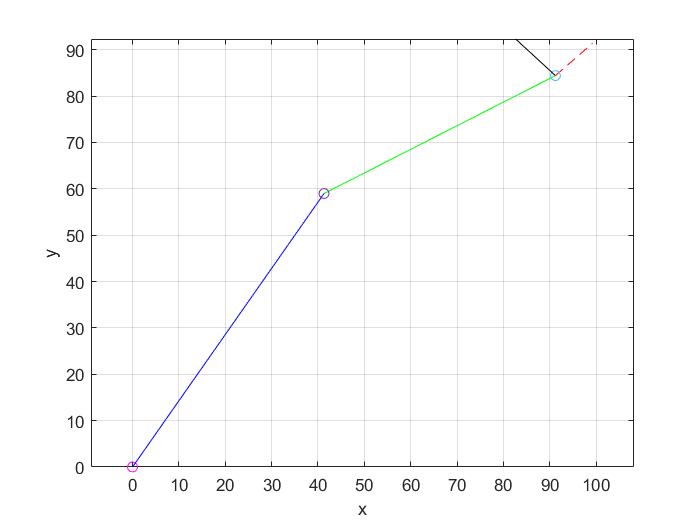

syms x
plot(0,0,'o','Color','magenta'); xlabel('x'); ylabel('y');hold on;grid on; % označi ishodište
axis equal;
x1=a1*cos(q1);
y1=a1*sin(q1);
l1=y1-x1*tan(q1+q2);
y01=x*tan(q1+q2)+l1;
fplot(y01,[x1 px],'Color','green')

y02=x*tan(q1);
fplot(y02,[0 x1],'Color','blue') %Crtanje nadlaktice robota
plot(x1,y1,'o') %Lakat robota

k=tan(q1+q2+q3); %Nagib pravca
l=py-k*px; %odsjecak na osi y
y03=x*k+l; %Eksplicitna jednadžba pravca
fplot(y03,[px px+Tr],'--r') %Crtanje šake robota
plot(px,py,'o') %Pocetak alata robota

x4=a2*cos(q1+q2)+a1*cos(q1);
y4=a2*sin(q1+q2)+a1*sin(q1);
x04=[x4 x4+vx];
y04=[y4 y4+vy];
line(x04,y04,[0,0],'Color','black') %Crtanje vektora brzine